cd('/Users/sushant/Desktop/ITC/JIPITE')
filename = 'MX201 Vibration Data for analysis.xlsx';
data = readtable(filename, 'VariableNamingRule', 'preserve');

data.Properties.VariableNames = {'DateTime','X_RMS','Y_RMS','Z_RMS','XRMS_Trend','YRMS_Trend','ZRMS_Trend'};
data.DateTime = datetime(data.DateTime);

validIdx = data.X_RMS > 0 | data.Y_RMS > 0 | data.Z_RMS > 0;
data = data(validIdx, :);

features = table;
features.XRMS = data.X_RMS;
features.YRMS = data.Y_RMS;
features.ZRMS = data.Z_RMS;
features.XRMS_Trend = data.XRMS_Trend;
features.YRMS_Trend = data.YRMS_Trend;
features.ZRMS_Trend = data.ZRMS_Trend;
features.MagRMS = sqrt(data.X_RMS.^2 + data.Y_RMS.^2 + data.Z_RMS.^2);
features.dXRMS = [NaN; diff(data.X_RMS)];
features.dYRMS = [NaN; diff(data.Y_RMS)];
features.dZRMS = [NaN; diff(data.Z_RMS)];
features = rmmissing(features);  % remove NaNs

X = normalize(features{:,:}, 'range');

numTrain = round(0.5 * size(X, 1));
XTrain = {X(1:numTrain, :)'};  
Xseq   = {X'};                         

%% Define network
layers = [
    sequenceInputLayer(size(X, 2))
    fullyConnectedLayer(32)
    reluLayer
    fullyConnectedLayer(16)
    reluLayer
    fullyConnectedLayer(32)
    reluLayer
    fullyConnectedLayer(size(X,2))
    regressionLayer
];

options = trainingOptions('adam', ...
    'MaxEpochs', 120, ...
    'MiniBatchSize', 32, ...
    'InitialLearnRate', 1e-3, ...
    'Shuffle', 'every-epoch', ...
    'Plots', 'training-progress', ...
    'Verbose', false);

%% Train
net = trainNetwork(XTrain, XTrain, layers, options);

%% Predict
Ypred = predict(net, Xseq);
reconLoss = sqrt(mean((Xseq{1} - Ypred{1}).^2, 1));  
timestamps = data.DateTime(end - numel(reconLoss) + 1:end);


%% Plot
figure;
plot(timestamps, reconLoss, 'b');
hold on;

% Threshold
p = 0.85;  % e.g., use 70% of timeline to compute threshold
N = size(reconLoss, 2);  % total number of samples in reconLoss
cutoffIdx = round(p * N);

threshold = prctile(reconLoss(1:cutoffIdx), 95);
yline(threshold, '--r', sprintf('Threshold (%.2f)', threshold), ...
    'LabelHorizontalAlignment', 'left', 'LabelVerticalAlignment', 'middle');


% Mark end of training
trainEndTime = data.DateTime(numTrain);
xline(trainEndTime, '--k', 'Training End', 'LabelVerticalAlignment','bottom');


% Automatically mark all timestamps where any RMS > 8.5 mm/s
faultIdx = data.X_RMS > 8.5 | data.Y_RMS > 8.5 | data.Z_RMS > 8.5;
faultTimes = unique(data.DateTime(faultIdx));

% for i = 1:numel(faultTimes)
%     xline(faultTimes(i), '--m');
% end

% Reconstruct the mapping between timestamps and RMSE
rmseTimestamps = timestamps;
rmseValues = reconLoss;


for i = 1:numel(faultTimes)
    faultTime = faultTimes(i);

    % Find exact match (down to the second)
    idx = find(rmseTimestamps == faultTime, 1);

    if ~isempty(idx) && rmseValues(idx) > threshold
        xline(faultTime, '--g');  % GREEN = fault + anomaly
    elseif ~isempty(idx)
        xline(faultTime, '--m');  % MAGENTA = fault only
    else
        xline(faultTime, '--m');  % fallback (no RMSE timestamp match)
    end
end

% Final plot settings
title('Reconstruction Error (Anomaly Score)');
ylabel('RMSE per time step');
xlabel('Time');
legend('Reconstruction Error', 'Threshold', 'Training End', 'Training Region', 'RMS > 8 mm/s', 'Location', 'northwest');
grid on;


% 🔁 Custom Batch-wise RMSE Tracking without ARIMA

totalSamples = size(X, 1);
batchLength = floor(0.5 * totalSamples);
stepSize = 100;

% Determine number of batches (ignore forecast horizon now)
numBatches = floor((totalSamples - batchLength) / stepSize);

% Initialize results table (ARIMA removed)
results = table('Size', [numBatches 4], ...
    'VariableTypes', {'double','datetime','double','cell'}, ...
    'VariableNames', {'BatchNumber','BatchStartTime','Threshold','RMSE'});

% Save original training batch RMSE and threshold (first half of data)
XOriginalTrain = X(1:batchLength, :)';
YOriginalPred = predict(net, {XOriginalTrain});
reconTrain = sqrt(mean((XOriginalTrain - YOriginalPred{1}).^2, 1));
thresholdOriginal = prctile(reconTrain, 95);

% Store separately
originalTrainingRMSE = reconTrain;
originalTrainingThreshold = thresholdOriginal;

% Loop through batches (no ARIMA)
% for b = 1:min(10, numBatches)  % or use 1:numBatches for full run
for b = 1:numBatches
    idxStart = 1 + (b-1) * stepSize;
    idxEnd = idxStart + batchLength - 1;
    fprintf("Batch %d | idxStart: %d | idxEnd: %d | total: %d\n", b, idxStart, idxEnd, totalSamples);
    if idxEnd > totalSamples
        break;
    end

    % Extract batch and train autoencoder
    XBatch = X(idxStart:idxEnd, :);
    XBatchCell = {XBatch'};

    layers = [
        sequenceInputLayer(size(X, 2))
        fullyConnectedLayer(32)
        reluLayer
        fullyConnectedLayer(16)
        reluLayer
        fullyConnectedLayer(32)
        reluLayer
        fullyConnectedLayer(size(X,2))
        regressionLayer
    ];

    options = trainingOptions('adam', ...
        'MaxEpochs', 120, ...
        'MiniBatchSize', 32, ...
        'InitialLearnRate', 1e-3, ...
        'Shuffle', 'every-epoch', ...
        'Plots', 'none', ...
        'Verbose', false);

    net = trainNetwork(XBatchCell, XBatchCell, layers, options);

    % Compute RMSE for the batch
    YpredBatch = predict(net, XBatchCell);
    reconBatch = sqrt(mean((XBatchCell{1} - YpredBatch{1}).^2, 1));
    thresholdBatch = prctile(reconBatch, 95);

    % Store results
    results.BatchNumber(b) = b;
    results.BatchStartTime(b) = timestamps(idxStart);
    results.Threshold(b) = thresholdBatch;
    results.RMSE{b} = reconBatch;
end

nonEmptyRows = find(~cellfun(@isempty, results.RMSE));
fprintf('Batches stored: %s\n', mat2str(nonEmptyRows));

% Display table
disp(results);

fprintf("Number of rows in results: %d\n", height(results));

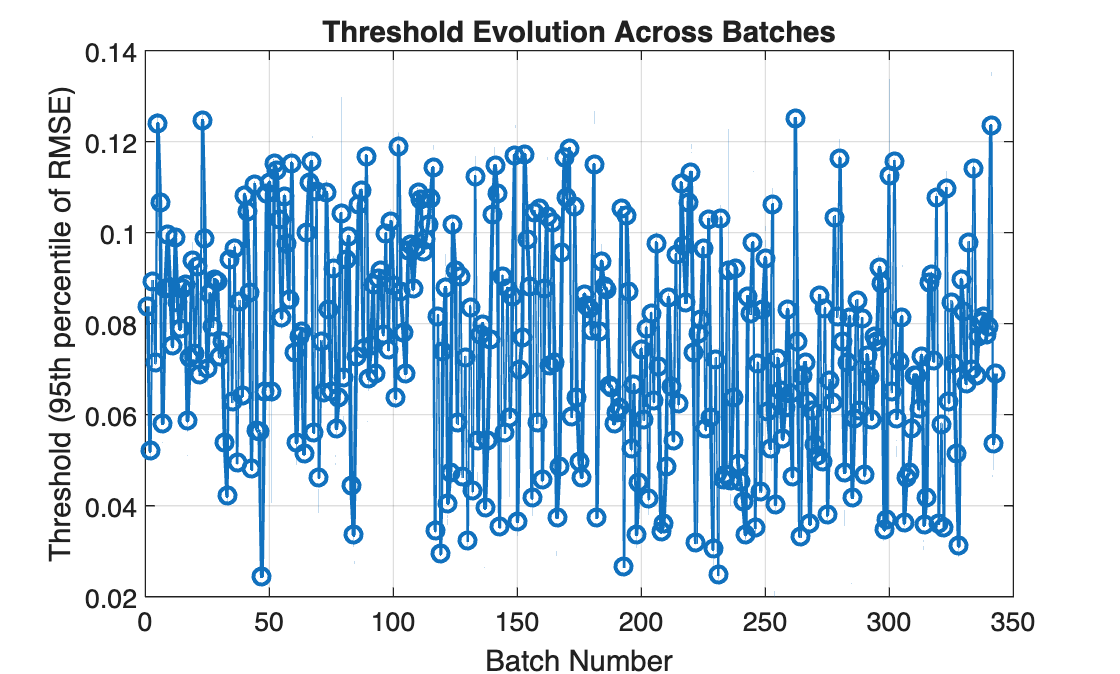

figure;
plot(results.BatchNumber, results.Threshold, '-o', 'LineWidth', 1.5);
xlabel('Batch Number');
ylabel('Threshold (95th percentile of RMSE)');
title('Threshold Evolution Across Batches');
grid on;

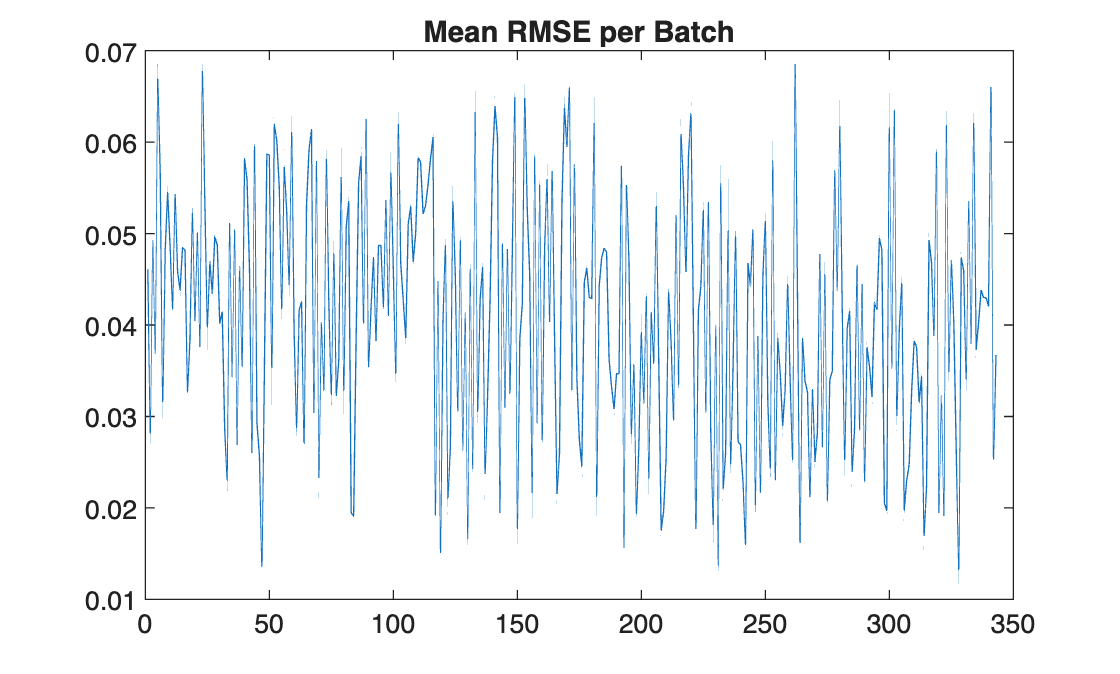



avgRMSE = cellfun(@mean, results.RMSE);
plot(results.BatchNumber, avgRMSE);
title('Mean RMSE per Batch');

%% --------------------------------------------
% 📈 Forecasting RMSE 600 Steps Ahead Using LSTM
% --------------------------------------------

% 1. Smooth RMSE (if not already done)
if ~exist('smoothRMSE', 'var')
    smoothRMSE = movmean(reconLoss, 25);  % You can adjust window
end

% 2. Prepare training data: past 50 → next 1
windowSize = 50;
X_lstm = {};
Y_lstm = {};

for i = 1:(length(smoothRMSE) - windowSize - 1)
    X_lstm{end+1} = smoothRMSE(i : i + windowSize - 1);  % column vector
    Y_lstm{end+1} = smoothRMSE(i + windowSize);          % scalar
end

X_lstm = X_lstm';
Y_lstm = Y_lstm';

% Wrap targets into 1×1 sequences
Y_lstm = cell2mat(Y_lstm);  % Converts to numeric vector (N×1)

% 3. Define LSTM network
inputSize = 1;
numHiddenUnits = 50;
numOutputs = 1;

layersLSTM = [
    sequenceInputLayer(inputSize)
    lstmLayer(numHiddenUnits, 'OutputMode','last')  % <— fix is here
    fullyConnectedLayer(numOutputs)
    regressionLayer
];

optionsLSTM = trainingOptions('adam', ...
    'MaxEpochs', 100, ...
    'MiniBatchSize', 32, ...
    'InitialLearnRate', 0.005, ...
    'GradientThreshold', 1, ...
    'Shuffle', 'every-epoch', ...
    'Plots', 'training-progress', ...
    'Verbose', false);

% 4. Train LSTM
fprintf("⏳ Training LSTM on smoothed RMSE...\n");
netLSTM = trainNetwork(X_lstm, Y_lstm, layersLSTM, optionsLSTM);
fprintf("✅ LSTM training complete.\n");

% 5. Recursive forecast for 600 steps
forecastSteps = 600;
inputSeq = smoothRMSE(end - windowSize + 1 : end);  % last known window
forecastRMSE = zeros(1, forecastSteps);

%% --------------------------------------------
% 🔁 Batch-wise Forecasting Using Pretrained LSTM
% --------------------------------------------

forecastSteps = 600;
windowSize = 50;

% Use same threshold rule: 95th percentile of early 85% of signal
p = 0.85;
cutoffIdx = round(p * length(smoothRMSE));
threshold = prctile(smoothRMSE(1:cutoffIdx), 95);

% Reuse your earlier batch definitions
batchResults = table('Size', [numBatches, 5], ...
    'VariableTypes', {'double','datetime','logical','double','cell'}, ...
    'VariableNames', {'BatchNumber','BatchStartTime','AnomalyPredicted','StepsUntilThreshold','ForecastRMSE'});

fprintf("🚀 Starting batch-wise forecasting...\n");

for b = 1:numBatches
    idxStart = 1 + (b-1) * stepSize;
    idxEnd = idxStart + batchLength - 1;

    if idxEnd > length(smoothRMSE)
        break;
    end

    % Prepare input for forecast
    batchSeq = smoothRMSE(idxStart : idxEnd);
    inputSeq = batchSeq(end - windowSize + 1 : end);  % last 50 points

    inputSeq = inputSeq(:)';  % row vector, shape [1 × 50]
    forecastRMSE = zeros(1, forecastSteps);

    for i = 1:forecastSteps
        next = predict(netLSTM, {inputSeq});
        forecastRMSE(i) = double(next);
        inputSeq = [inputSeq(2:end), double(next)];
    end

    % Find first time threshold is crossed
    idxCross = find(forecastRMSE > threshold, 1);

    % Save
    batchResults.BatchNumber(b) = b;
    batchResults.BatchStartTime(b) = timestamps(idxStart);
    batchResults.ForecastRMSE{b} = forecastRMSE;

    if ~isempty(idxCross)
        batchResults.AnomalyPredicted(b) = true;
        batchResults.StepsUntilThreshold(b) = idxCross;
    else
        batchResults.AnomalyPredicted(b) = false;
        batchResults.StepsUntilThreshold(b) = NaN;
    end
end

fprintf("✅ Forecasting complete for %d batches.\n", height(batchResults));
disp(batchResults);

anomalies = batchResults(batchResults.AnomalyPredicted, :);
disp(anomalies);
numTrue = sum(batchResults.AnomalyPredicted);
fprintf("✅ Total batches with predicted anomaly: %d\n", numTrue);

% Initialize threshold vector
fullThreshold = zeros(size(reconLoss));

% 1. Assign original threshold to first half
fullThreshold(1:numTrain) = thresholdOriginal;

% 2. Assign rolling thresholds batch-wise to the second half
for b = 1:height(results)
    idxStart = numTrain + (b - 1) * stepSize + 1;
    idxEnd = min(idxStart + stepSize - 1, length(reconLoss));

    fullThreshold(idxStart:idxEnd) = results.Threshold(b);
end

% Combine into a table for easy viewing
thresholdTable = table(timestamps(:), reconLoss(:), fullThreshold(:), ...
    'VariableNames', {'Timestamp', 'RMSE', 'Threshold'});

% Preview a few rows
disp(thresholdTable(1:10, :));

         Timestamp            RMSE      Threshold
    ____________________    ________    _________

    17-Dec-2024 10:11:49    0.086415    0.051104 
    17-Dec-2024 10:12:50      0.0821    0.051104 
    17-Dec-2024 10:13:51    0.082186    0.051104 
    17-Dec-2024 10:14:52    0.088705    0.051104 
    17-Dec-2024 10:15:53    0.091291    0.051104 
    17-Dec-2024 10:16:54    0.090495    0.051104 
    17-Dec-2024 10:17:55     0.08814    0.051104 
    17-Dec-2024 10:18:56     0.08697    0.051104 
    17-Dec-2024 10:19:57    0.088619    0.051104 
    17-Dec-2024 10:20:58     0.08733    0.051104 



disp(thresholdTable(end-10:end, :));

         Timestamp           RMSE      Threshold
    ____________________    _______    _________

    30-Jun-2025 23:06:32    0.33409        0    
    30-Jun-2025 23:11:32    0.33289        0    
    30-Jun-2025 23:16:32    0.33356        0    
    30-Jun-2025 23:21:32    0.33287        0    
    30-Jun-2025 23:26:32    0.33383        0    
    30-Jun-2025 23:31:32     0.3331        0    
    30-Jun-2025 23:36:32    0.33458        0    
    30-Jun-2025 23:41:32    0.33349        0    
    30-Jun-2025 23:46:32    0.33314        0    
    30-Jun-2025 23:51:32    0.33372        0    
    30-Jun-2025 23:56:32    0.33635        0    



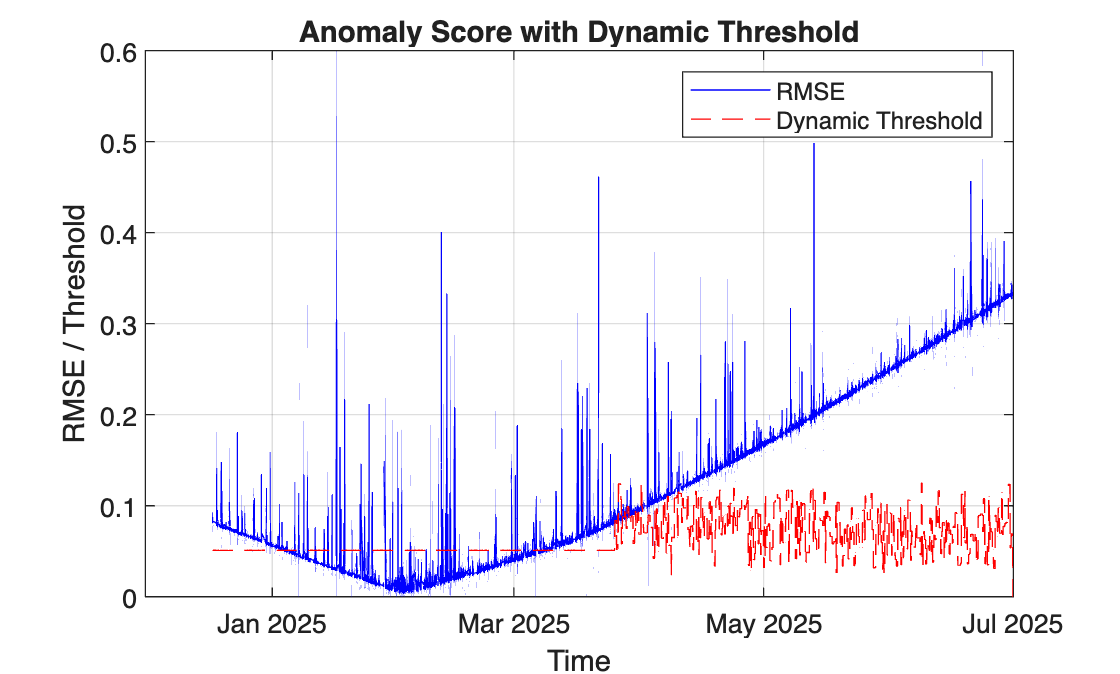


figure;
plot(timestamps, reconLoss, 'b');
hold on;
plot(timestamps, fullThreshold, 'r--');
xlabel('Time');
ylabel('RMSE / Threshold');
legend('RMSE', 'Dynamic Threshold');
title('Anomaly Score with Dynamic Threshold');
grid on;

% Initialize
fullThreshold = zeros(size(reconLoss));

% First half → constant original threshold
fullThreshold(1:numTrain) = thresholdOriginal;

% Second half → use threshold per batch
for b = 1:height(results)
    % indexStart should start immediately after training
    idxStart = numTrain + (b - 1) * stepSize + 1;
    idxEnd = min(idxStart + stepSize - 1, length(fullThreshold));  % bound check

    fullThreshold(idxStart:idxEnd) = results.Threshold(b);
end

% Replot RMSE with dynamic thresholds
figure;
plot(timestamps, reconLoss, 'b'); hold on;
plot(timestamps, fullThreshold, 'r--');
xlabel('Time'); ylabel('RMSE / Threshold');
title('Anomaly Score with Dynamic Threshold');
legend('RMSE','Dynamic Threshold');
grid on;